# **CPSC 302: Assignment 8**

# Nicholas Hu

## Question 3

**(a)**

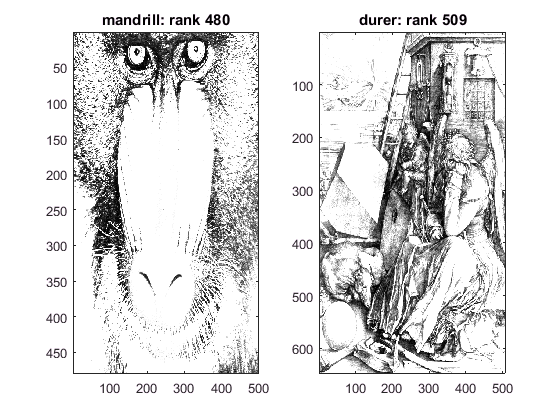

clear variables; clc; format;

load mandrill;
M = X;

load durer;
D = X;

colormap(gray);
subplot(1, 2, 1);
image(M);
title(sprintf('mandrill: rank %d', rank(M)));
subplot(1, 2, 2);
image(D);
title(sprintf('durer: rank %d', rank(D)));

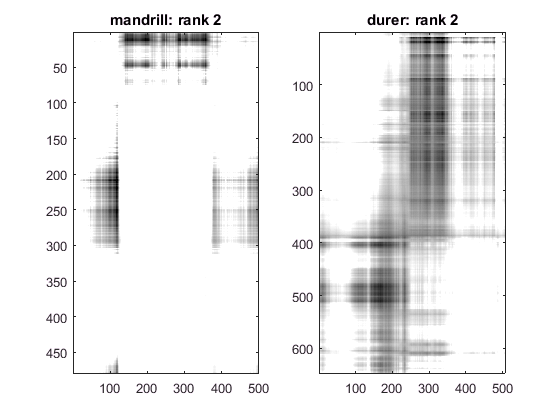

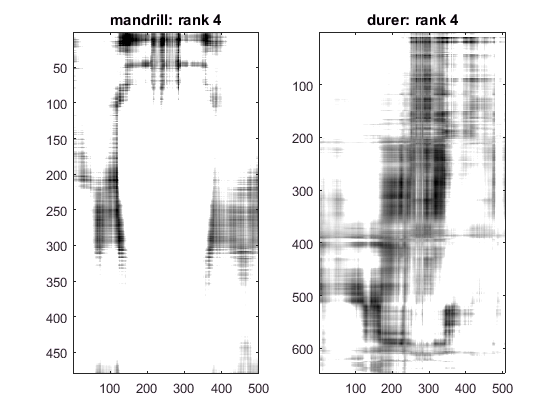

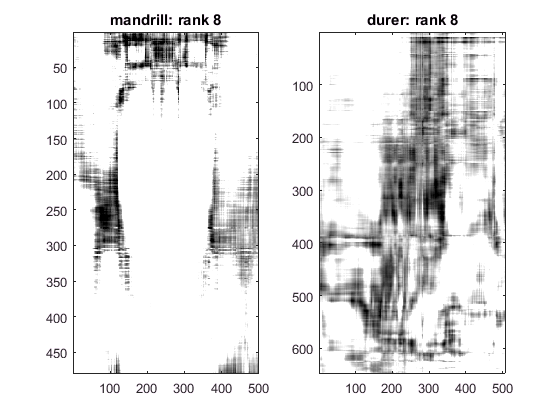

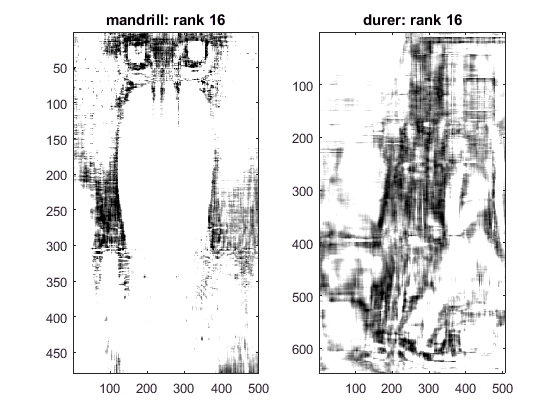

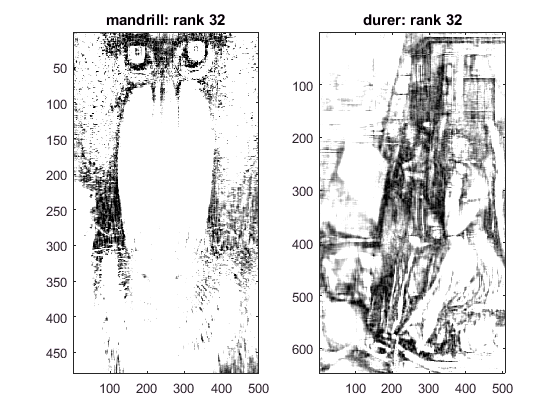

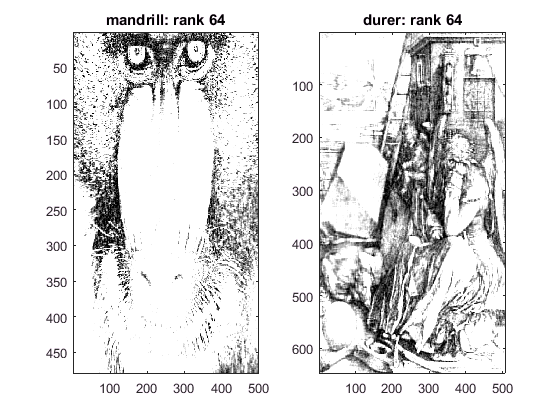

[UM, SM, VM] = svd(M, 'econ');
[UD, SD, VD] = svd(D, 'econ');

for r = 2.^(1:6)
    figure;
    colormap(gray);
    s = 1:r;
    
    T = UM(:, s) * SM(s, s) * VM(:, s)';
    subplot(1, 2, 1);
    image(T);
    title(sprintf('mandrill: rank %d', r));
    
    T = UD(:, s) * SD(s, s) * VD(:, s)';
    subplot(1, 2, 2);
    image(T);
    title(sprintf('durer: rank %d', r));
end

**(b)**

The number of storage locations required for a rank $r$ approximation of an image is $r (m + n + 1)$, where $m$ is the number of rows in the image matrix (i.e., its height) and $n$ is the number of columns (i.e., its width). (The items stored are the truncated $U$ and $V$ matrices, along with an $r$-vector containing the diagonal of the truncated $\Sigma$ matrix.)

The number of storage locations required for the full matrix is $mn$.

The truncated SVD approximations are reasonable for $r = 64$; however, the technique seems to be more effective for the mandrill image than for Durer's drawing. This is because the drawing contains many fine details (i.e., high-frequency components) which are blurred and garbled in low rank approximations.